clear all
clc

syms y x real

p_0_x = -0.8

p_0_x = -0.8000

p_0_y = 1.1

p_0_y = 1.1000


l1 = 0.5

l1 = 0.5000

l2 = 0.4

l2 = 0.4000


v = 0.3

v = 0.3000


beta = deg2rad(-20)

beta = -0.3491


m = tan(beta)

m = -0.3640


R = l1 + l2

R = 0.9000


eqn1 = y == m*(x - p_0_x) + p_0_y 

$$eqn1 = y=\frac{4553273276219211}{5629499534213120}-\frac{1639176211415221\,x}{4503599627370496}$$

eqn2 = x^2 + y^2 == R^2

$$eqn2 = x^{2}+y^{2}=\frac{81}{100}$$


eqns = [eqn1, eqn2]

$$eqns = \left(\begin{array}{cc} y=\frac{4553273276219211}{5629499534213120}-\frac{1639176211415221\,x}{4503599627370496} & x^{2}+y^{2}=\frac{81}{100} \end{array}\right)$$


solution = solve(eqns, [y, x])

solution = struct with fields:
    y: [2×1 sym]
    x: [2×1 sym]



disp("x")

x


double(solution.x)

ans =    -0.1930
    0.7129


disp("y")

y


double(solution.y)

ans =     0.8791
    0.5494



% let's take the solution with x < 0 
% since it's the first intersection 
% encountered by the point
p_int = [double(solution.x(1)); double(solution.y(1))]

p_int =    -0.1930
    0.8791


## now let's write the trajectory of the point in the line in time

syms t

v_vector = v*[cos(beta); sin(beta)]

v_vector =     0.2819
   -0.1026



p_line = p_int + t*v_vector

$$p\_line = \left(\begin{array}{c} \frac{2539199602088533\,t}{9007199254740992}-\frac{1738273701912061}{9007199254740992}\\ \frac{7917917128454449}{9007199254740992}-\frac{7393544592166489\,t}{72057594037927936} \end{array}\right)$$


% we should find p(t) for the robot

p_rv = double(subs(p_line, t, 2))

p_rv =     0.3708
    0.6739


## Inverse kinematics of the 2R

p_x = p_rv(1)

p_x = 0.3708

p_y = p_rv(2) 

p_y = 0.6739


l1 = 0.5

l1 = 0.5000

l2 = 0.4

l2 = 0.4000


c2 = (p_x^2 + p_y^2 - (l1^2 + l2^2)) / (2*l1*l2);

s2_pos = sqrt(1 - c2^2);
s2_neg = -sqrt(1 - c2^2);

q2_pos = atan2(s2_pos,c2);
q2_neg = atan2(s2_neg,c2);

q1_pos = atan2(p_y,p_x) - atan2(l2*s2_pos, l1 + l2*c2);
q1_neg = atan2(p_y,p_x) - atan2(l2*s2_neg, l1 + l2*c2);

q_first = [q1_pos; q2_pos];
q_second = [q1_neg; q2_neg];

disp("First solution:");

First solution:


% elbow left solution
disp(q_first);

    0.5859
    1.0996



disp("Second solution:");

Second solution:


% elbow right solution
disp(q_second);

    1.5495
   -1.0996




% let's take the elbow right solution
q_rv = q_second

q_rv =     1.5495
   -1.0996


## Jacobian of the 2R

syms q1 q2

p = [l1*cos(q1) + l2*cos(q1 + q2);
     l1*sin(q1) + l2*sin(q1 + q2);]

$$p = \left(\begin{array}{c} \frac{2\,\cos\left(q_{1}+q_{2}\right)}{5}+\frac{\cos\left(q_{1}\right)}{2}\\ \frac{2\,\sin\left(q_{1}+q_{2}\right)}{5}+\frac{\sin\left(q_{1}\right)}{2} \end{array}\right)$$


J = simplify(jacobian(p, [q1, q2]), steps=100)

$$J = \left(\begin{array}{cc} -\frac{2\,\sin\left(q_{1}+q_{2}\right)}{5}-\frac{\sin\left(q_{1}\right)}{2} & -\frac{2\,\sin\left(q_{1}+q_{2}\right)}{5}\\ \frac{2\,\cos\left(q_{1}+q_{2}\right)}{5}+\frac{\cos\left(q_{1}\right)}{2} & \frac{2\,\cos\left(q_{1}+q_{2}\right)}{5} \end{array}\right)$$


inv_J = simplify(inv(J), steps=100)

$$inv\_J = \left(\begin{array}{cc} \frac{2\,\cos\left(q_{1}+q_{2}\right)}{\sin\left(q_{2}\right)} & \frac{2\,\sin\left(q_{1}+q_{2}\right)}{\sin\left(q_{2}\right)}\\ -\frac{4\,\cos\left(q_{1}+q_{2}\right)+5\,\cos\left(q_{1}\right)}{2\,\sin\left(q_{2}\right)} & -\frac{4\,\sin\left(q_{1}+q_{2}\right)+5\,\sin\left(q_{1}\right)}{2\,\sin\left(q_{2}\right)} \end{array}\right)$$

## let's write the condition for the trajectory of the robot

% position
q_initial = [pi, 0]

q_initial =     3.1416         0


q_final = q_rv

q_final =     1.5495
   -1.0996




inv_J_final = double(subs(inv_J, [q1, q2], [q_rv(1), q_rv(2)]));

% velocity
q_dot_initial = [0; 0]

q_dot_initial =      0
     0


q_dot_final = inv_J_final*[v*cos(beta); v*sin(beta)] % WARNING, PAY ATTENTION TO THIS! V IS THE CARTESIAN VELOCITY

q_dot_final =    -0.4696
    0.1986


% BUT SINCE WE ARE WRITING A JOINT SPACE TRAJECTORY, WE NEED THE JOINT VELOCITY




## Now let's find the coefficient of the cubic for joint 1

syms vf qi qf Ca0 Ca1 Ca2 Ca3 t ti tf T

%% IMPORTANT NOTE: Ca0, Ca1, ... are delta_Q * a, delta_Q * b, ... respectively

assume(t, 'positive')
assume(ti, 'positive')
assume(tf, 'positive')
assume(T, 'positive')

%% CHANGE THESE TO PLOT CORRECTLY THE FUNCTIONS
%% LEAVE THEM COMMENTED IF YOU WANT THE FUNCTIONS EXPRESSED IN SYMBOLS 
ti = 0

ti = 0

qi = q_initial(1)

qi = 3.1416

qf = q_final(1)

qf = 1.5495

vf = q_dot_final(1)

vf = -0.4696

% tf is not substituted since we use T and we substitute T afterwards 


T = 2 

T = 2


% condition
% initial point q(ti)
q_t = qi

q_t = 3.1416


% final point
q_T = qf

q_T = 1.5495


% starts at rest
q_dot_t = 0

q_dot_t = 0


% finishes with a velocity different from 0
q_dot_T = vf

q_dot_T = -0.4696


%% THIS MAY CHANGE, E.G. IF YOU HAVE 2 SPLINE
% T = tf - ti
tau = (t - ti)/T 

$$tau = \frac{t}{2}$$


% cubic q(t)
q = qi + Ca0 + Ca1 * tau + Ca2 * tau^2 + Ca3 * tau^3

$$q = \frac{{\mathrm{Ca}}_{3}\,t^{3}}{8}+\frac{{\mathrm{Ca}}_{2}\,t^{2}}{4}+\frac{{\mathrm{Ca}}_{1}\,t}{2}+{\mathrm{Ca}}_{0}+\pi$$


% q(ti) is just qi

% q(tf)
q_subs_qf = simplify(subs(q, t, tf), steps = 100) 

$$q\_subs\_qf = \frac{{\mathrm{Ca}}_{3}\,{\mathrm{tf}}^{3}}{8}+\frac{{\mathrm{Ca}}_{2}\,{\mathrm{tf}}^{2}}{4}+\frac{{\mathrm{Ca}}_{1}\,\mathrm{tf}}{2}+{\mathrm{Ca}}_{0}+\pi$$



% q_dot(t)
q_dot = simplify(diff(q, t), steps = 100)

$$q\_dot = \frac{3\,{\mathrm{Ca}}_{3}\,t^{2}}{8}+\frac{{\mathrm{Ca}}_{2}\,t}{2}+\frac{{\mathrm{Ca}}_{1}}{2}$$


% q_dot(ti)
q_dot_subs_qi = simplify(subs(q_dot, t, ti), steps = 100)

$$q\_dot\_subs\_qi = \frac{{\mathrm{Ca}}_{1}}{2}$$


% q_dot(tf)
q_dot_subs_qf = simplify(subs(q_dot, t, tf), steps = 100)

$$q\_dot\_subs\_qf = \frac{3\,{\mathrm{Ca}}_{3}\,{\mathrm{tf}}^{2}}{8}+\frac{{\mathrm{Ca}}_{2}\,\mathrm{tf}}{2}+\frac{{\mathrm{Ca}}_{1}}{2}$$



% q_dot_dot(t)
q_dot_dot = simplify(diff(q_dot, t), steps=1000)

$$q\_dot\_dot = \frac{{\mathrm{Ca}}_{2}}{2}+\frac{3\,{\mathrm{Ca}}_{3}\,t}{4}$$


% q_dot_dot(ti)
q_dot_dot_subs_qi = simplify(subs(q_dot_dot, t, ti), steps = 100)

$$q\_dot\_dot\_subs\_qi = \frac{{\mathrm{Ca}}_{2}}{2}$$


% q_dot_dot(tf)
q_dot_dot_subs_qf = simplify(subs(q_dot_dot, t, tf), steps = 100)

$$q\_dot\_dot\_subs\_qf = \frac{{\mathrm{Ca}}_{2}}{2}+\frac{3\,{\mathrm{Ca}}_{3}\,\mathrm{tf}}{4}$$



%   Ca0 Ca1 Ca2 Ca3
A = [1, 0,  0,  0,; % q(0)   
     1, 1 , 1,  1;  % q(1)
     0, 1/T, 0, 0 % q_dot(0)
     0, 1/T, 2/T, 3/T]  %q_dot(1)

A =     1.0000         0         0         0
    1.0000    1.0000    1.0000    1.0000
         0    0.5000         0         0
         0    0.5000    1.0000    1.5000



B = [0;     % q(0)
     qf-qi; % q(1)
     0;     % q_dot(0)
     vf]    % q_dot(1)

B =          0
   -1.5921
         0
   -0.4696



%A_B = simplify(A\B, steps = 100)
A_B = A\B

A_B =          0
         0
   -3.8370
    2.2449




Ca0_n = A_B(1)

Ca0_n = 0

Ca1_n = A_B(2)

Ca1_n = 0

Ca2_n = A_B(3)

Ca2_n = -3.8370

Ca3_n = A_B(4)

Ca3_n = 2.2449


% q(t) with Ca0, Ca1, Ca2, Ca3 substituted 
q_subs = vpa(simplify(subs(q, [Ca0, Ca1, Ca2, Ca3], [Ca0_n, Ca1_n, Ca2_n, Ca3_n]), steps = 100))

$$q\_subs = 0.28061103663259834295473638121621\,t^{3}-0.95924159377086304356652135538752\,t^{2}+3.1415926535897932384626433832795$$


% q_dot(t) with Ca0, Ca1, Ca2, Ca3 substituted
q_dot_subs = vpa(simplify(subs(q_dot, [Ca0, Ca1, Ca2, Ca3], [Ca0_n, Ca1_n, Ca2_n, Ca3_n]), steps = 100))

$$q\_dot\_subs = 0.00000000000000011102230246251565404236316680908\,t\,\left(7582558560087711.0\,t-17280160337058958.0\right)$$


% q_dot_dot(t) with Ca0, Ca1, Ca2, Ca3 substituted
q_dot_dot_subs = vpa(simplify(subs(q_dot_dot, [Ca0, Ca1, Ca2, Ca3], [Ca0_n, Ca1_n, Ca2_n, Ca3_n]), steps = 100))

$$q\_dot\_dot\_subs = 1.6836662197955900577284182872972\,t-1.918483187541726087133042710775$$

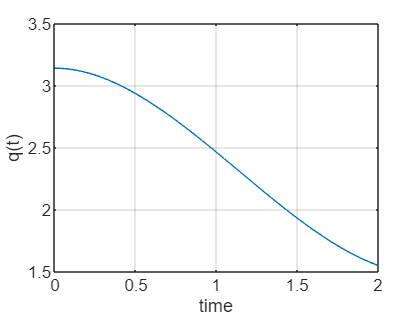


%% PLOTTING
% T_val is ti - tf
T_val = 2; 
time = 0: 0.01: T_val;
q_values = subs(q_subs, [{t} {T}], [{time} {T_val}]);
q_dot_values = subs(q_dot_subs, [{t} {T}], [{time} {T_val}]);
q_dot_dot_values = subs(q_dot_dot_subs, [{t} {T}], [{time} {T_val}]);

figure;
plot(time, q_values)
hold on;
grid on;
xlabel("time");
ylabel("q(t)")

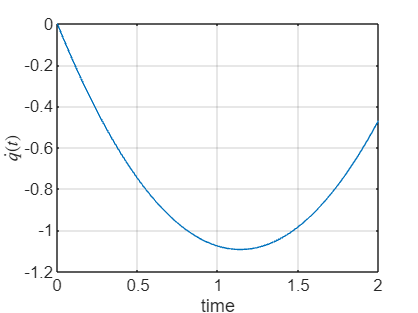


figure;
plot(time, q_dot_values)
hold on;
grid on;
xlabel("time");
ylabel("$\dot{q}(t)$", 'Interpreter', 'latex')

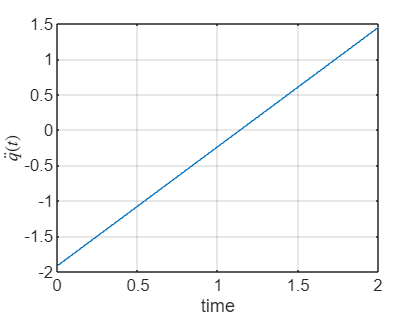



figure;
plot(time, q_dot_dot_values)
hold on;
grid on;
xlabel("time");
ylabel("$\ddot{q}(t)$", 'Interpreter', 'latex')

## Now for joint 2


%% IMPORTANT NOTE: Ca0, Ca1, ... are delta_Q * a, delta_Q * b, ... respectively


%% CHANGE THESE TO PLOT CORRECTLY THE FUNCTIONS
%% LEAVE THEM COMMENTED IF YOU WANT THE FUNCTIONS EXPRESSED IN SYMBOLS 
ti = 0

ti = 0

qi = q_initial(2)

qi = 0

qf = q_final(2)

qf = -1.0996

vf = q_dot_final(2)

vf = 0.1986

% tf is not substituted since we use T and we substitute T afterwards 

T = 2 

T = 2


% condition
% initial point q(ti)
q_t = qi

q_t = 0


% final point
q_T = qf

q_T = -1.0996


% starts at rest
q_dot_t = 0

q_dot_t = 0


% finishes with a velocity different from 0
q_dot_T = vf

q_dot_T = 0.1986


%% THIS MAY CHANGE, E.G. IF YOU HAVE 2 SPLINE
% T = tf - ti
tau = (t - ti)/T 

$$tau = \frac{t}{2}$$


% cubic q(t)
q = qi + Ca0 + Ca1 * tau + Ca2 * tau^2 + Ca3 * tau^3

$$q = \frac{{\mathrm{Ca}}_{3}\,t^{3}}{8}+\frac{{\mathrm{Ca}}_{2}\,t^{2}}{4}+\frac{{\mathrm{Ca}}_{1}\,t}{2}+{\mathrm{Ca}}_{0}$$


% q(ti) is just qi

% q(tf)
q_subs_qf = simplify(subs(q, t, tf), steps = 100) 

$$q\_subs\_qf = \frac{{\mathrm{Ca}}_{3}\,{\mathrm{tf}}^{3}}{8}+\frac{{\mathrm{Ca}}_{2}\,{\mathrm{tf}}^{2}}{4}+\frac{{\mathrm{Ca}}_{1}\,\mathrm{tf}}{2}+{\mathrm{Ca}}_{0}$$



% q_dot(t)
q_dot = simplify(diff(q, t), steps = 100)

$$q\_dot = \frac{3\,{\mathrm{Ca}}_{3}\,t^{2}}{8}+\frac{{\mathrm{Ca}}_{2}\,t}{2}+\frac{{\mathrm{Ca}}_{1}}{2}$$


% q_dot(ti)
q_dot_subs_qi = simplify(subs(q_dot, t, ti), steps = 100)

$$q\_dot\_subs\_qi = \frac{{\mathrm{Ca}}_{1}}{2}$$


% q_dot(tf)
q_dot_subs_qf = simplify(subs(q_dot, t, tf), steps = 100)

$$q\_dot\_subs\_qf = \frac{3\,{\mathrm{Ca}}_{3}\,{\mathrm{tf}}^{2}}{8}+\frac{{\mathrm{Ca}}_{2}\,\mathrm{tf}}{2}+\frac{{\mathrm{Ca}}_{1}}{2}$$



% q_dot_dot(t)
q_dot_dot = simplify(diff(q_dot, t), steps=1000)

$$q\_dot\_dot = \frac{{\mathrm{Ca}}_{2}}{2}+\frac{3\,{\mathrm{Ca}}_{3}\,t}{4}$$


% q_dot_dot(ti)
q_dot_dot_subs_qi = simplify(subs(q_dot_dot, t, ti), steps = 100)

$$q\_dot\_dot\_subs\_qi = \frac{{\mathrm{Ca}}_{2}}{2}$$


% q_dot_dot(tf)
q_dot_dot_subs_qf = simplify(subs(q_dot_dot, t, tf), steps = 100)

$$q\_dot\_dot\_subs\_qf = \frac{{\mathrm{Ca}}_{2}}{2}+\frac{3\,{\mathrm{Ca}}_{3}\,\mathrm{tf}}{4}$$



%   Ca0 Ca1 Ca2 Ca3
A = [1, 0,  0,  0,; % q(0)   
     1, 1 , 1,  1;  % q(1)
     0, 1/T, 0, 0 % q_dot(0)
     0, 1/T, 2/T, 3/T]  %q_dot(1)

A =     1.0000         0         0         0
    1.0000    1.0000    1.0000    1.0000
         0    0.5000         0         0
         0    0.5000    1.0000    1.5000



B = [0;     % q(0)
     qf-qi; % q(1)
     0;     % q_dot(0)
     vf]    % q_dot(1)

B =          0
   -1.0996
         0
    0.1986



%A_B = simplify(A\B, steps = 100)
A_B = A\B

A_B =          0
         0
   -3.6960
    2.5964




Ca0_n = A_B(1)

Ca0_n = 0

Ca1_n = A_B(2)

Ca1_n = 0

Ca2_n = A_B(3)

Ca2_n = -3.6960

Ca3_n = A_B(4)

Ca3_n = 2.5964


% q(t) with Ca0, Ca1, Ca2, Ca3 substituted 
q_subs = vpa(simplify(subs(q, [Ca0, Ca1, Ca2, Ca3], [Ca0_n, Ca1_n, Ca2_n, Ca3_n]), steps = 100))

$$q\_subs = 0.00000000000000011102230246251565404236316680908\,t^{2}\,\left(2923305761750257.0\,t-8322621299856120.0\right)$$


% q_dot(t) with Ca0, Ca1, Ca2, Ca3 substituted
q_dot_subs = vpa(simplify(subs(q_dot, [Ca0, Ca1, Ca2, Ca3], [Ca0_n, Ca1_n, Ca2_n, Ca3_n]), steps = 100))

$$q\_dot\_subs = 0.00000000000000033306690738754696212708950042725\,t\,\left(2923305761750257.0\,t-5548414199904080.0\right)$$


% q_dot_dot(t) with Ca0, Ca1, Ca2, Ca3 substituted
q_dot_dot_subs = vpa(simplify(subs(q_dot_dot, [Ca0, Ca1, Ca2, Ca3], [Ca0_n, Ca1_n, Ca2_n, Ca3_n]), steps = 100))

$$q\_dot\_dot\_subs = 1.9473128188287105455600567438523\,t-1.8479931584672026900761920842342$$

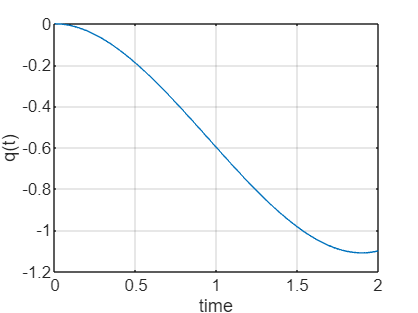


%% PLOTTING
% T_val is ti - tf
T_val = 2; 
time = 0: 0.01: T_val;
q_values = subs(q_subs, [{t} {T}], [{time} {T_val}]);
q_dot_values = subs(q_dot_subs, [{t} {T}], [{time} {T_val}]);
q_dot_dot_values = subs(q_dot_dot_subs, [{t} {T}], [{time} {T_val}]);

figure;
plot(time, q_values)
hold on;
grid on;
xlabel("time");
ylabel("q(t)")

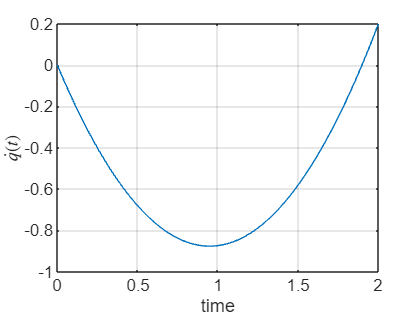


figure;
plot(time, q_dot_values)
hold on;
grid on;
xlabel("time");
ylabel("$\dot{q}(t)$", 'Interpreter', 'latex')

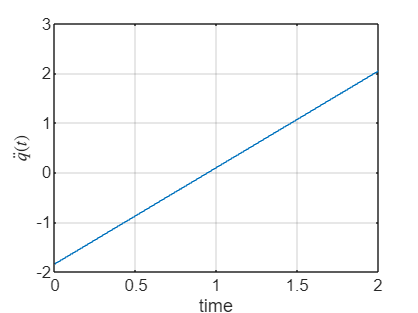



figure;
plot(time, q_dot_dot_values)
hold on;
grid on;
xlabel("time");
ylabel("$\ddot{q}(t)$", 'Interpreter', 'latex')